clear all

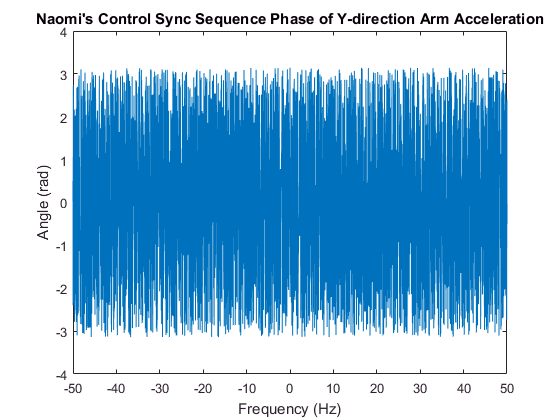

load controlsyncnaomi.mat
load controlsyncrachel.mat
Fs= 100;
N = length(controlsyncnaomi(:,1));
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);
plot(f,fftshift(angle(fft(controlsyncnaomi(:,5)))))
title("Naomi's Control Sync Sequence Phase of Y-direction Arm Acceleration")
xlabel('Frequency (Hz)')
ylabel('Angle (rad)')

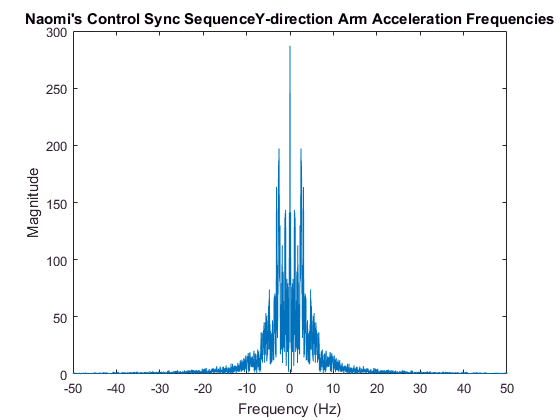

plot(f,abs(fftshift(fft(controlsyncnaomi(:,5)))))
title("Naomi's Control Sync SequenceY-direction Arm Acceleration Frequencies")
xlabel('Frequency (Hz)')
ylabel('Magnitude')

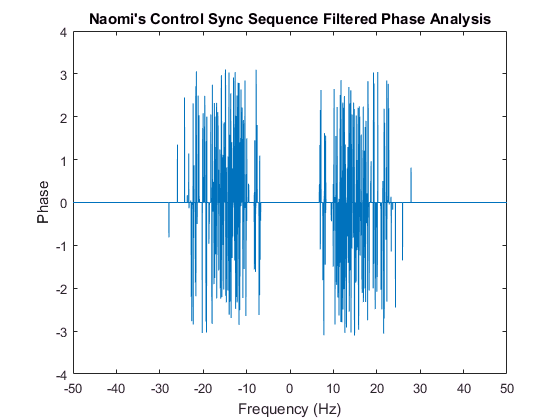

[f_control, mag_control, phase_control, bpm_control] = findbpmphase('controlsyncnaomi.mat', Fs, 'accel', 'y', 1, length(controlsyncnaomi));
plot(f_control, phase_control)
% hold on
% [f_controlr, mag_controlr, phase_controlr, bpm_controlr] = findbpmphase('controlsyncrachel.mat', Fs, 'accel', 'y', 1, length(controlsyncrachel));
% plot(f_controlr, phase_controlr)
% hold off
% legend('Naomi', 'Rachel')
title("Naomi's Control Sync Sequence Filtered Phase Analysis")
xlabel('Frequency (Hz)')
ylabel('Phase')

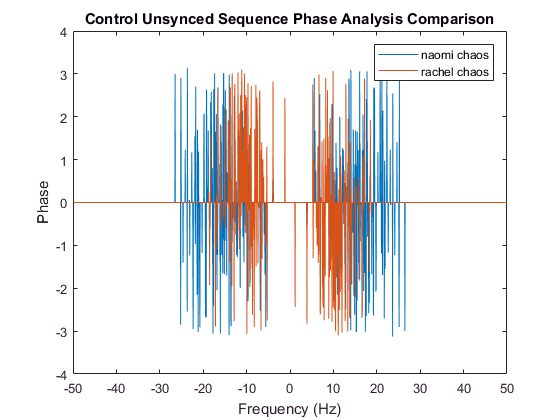

load controlchaosnaomi.mat
load controlchaosrachel.mat

[f_chaos, mag_chaos, phase_chaos, bpm_chaos] = findbpmphase('controlchaosnaomi.mat', Fs, 'accel', 'y', 1, length(controlchaosnaomi));
plot(f_chaos, phase_chaos)
hold on
[f_chaosr, mag_chaosr, phase_chaosr, bpm_chaosr] = findbpmphase('controlchaosrachel.mat', Fs, 'accel', 'y', 1, length(controlchaosrachel));
plot(f_chaosr, phase_chaosr)
hold off
legend('Naomi', 'Rachel')
title('Control Unsynced Sequence Phase Analysis Comparison')
xlabel('Frequency (Hz)')
ylabel('Phase')

load onthefloornaomi.mat
load onthefloorrachel.mat

[f_otf, mag_otf, phase_otf, bpm_otf] = findbpmphase('onthefloornaomi.mat', Fs, 'accel', 'y', 1, length(onthefloornaomi))

f_otf =   -49.9980  -49.9941  -49.9901  -49.9861  -49.9822  -49.9782  -49.9742  -49.9703  -49.9663  -49.9623  -49.9584  -49.9544  -49.9504  -49.9465  -49.9425  -49.9385  -49.9346  -49.9306  -49.9266  -49.9227  -49.9187  -49.9147  -49.9108  -49.9068  -49.9028  -49.8989  -49.8949  -49.8909  -49.8870  -49.8830  -49.8790  -49.8751  -49.8711  -49.8671  -49.8632  -49.8592  -49.8552  -49.8513  -49.8473  -49.8433  -49.8394  -49.8354  -49.8314  -49.8275  -49.8235  -49.8195  -49.8156  -49.8116  -49.8076  -49.8037


mag_otf =     1.0275
    0.6488
    0.5010
    1.5115
    1.7648
    0.6635
    1.2027
    0.4764
    0.5393
    0.3494


phase_otf =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


bpm_otf = 130.4089

[f_otfr, mag_otfr, phase_otfr, bpm_otfr] = findbpmphase('onthefloorrachel.mat', Fs, 'accel', 'y', 1, length(onthefloorrachel))

f_otfr =   -49.9980  -49.9940  -49.9901  -49.9861  -49.9821  -49.9781  -49.9741  -49.9702  -49.9662  -49.9622  -49.9582  -49.9542  -49.9503  -49.9463  -49.9423  -49.9383  -49.9343  -49.9304  -49.9264  -49.9224  -49.9184  -49.9144  -49.9105  -49.9065  -49.9025  -49.8985  -49.8945  -49.8906  -49.8866  -49.8826  -49.8786  -49.8746  -49.8707  -49.8667  -49.8627  -49.8587  -49.8547  -49.8508  -49.8468  -49.8428  -49.8388  -49.8349  -49.8309  -49.8269  -49.8229  -49.8189  -49.8150  -49.8110  -49.8070  -49.8030


mag_otfr =     6.8069
    7.4630
    8.3192
    6.4222
    5.4394
    5.0091
    4.7442
    4.3103
    6.1736
    8.8179


phase_otfr =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


bpm_otfr = 129.6510

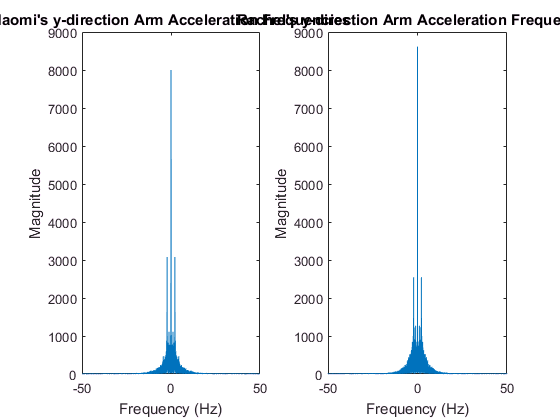

figure
subplot(1,2,1)
plot(f_otf,mag_otf)
title("Naomi's y-direction Arm Acceleration Frequencies")
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(1,2,2)
plot(f_otfr,mag_otfr)
title("Rachel's y-direction Arm Acceleration Frequencies")
xlabel('Frequency (Hz)')
ylabel('Magnitude')

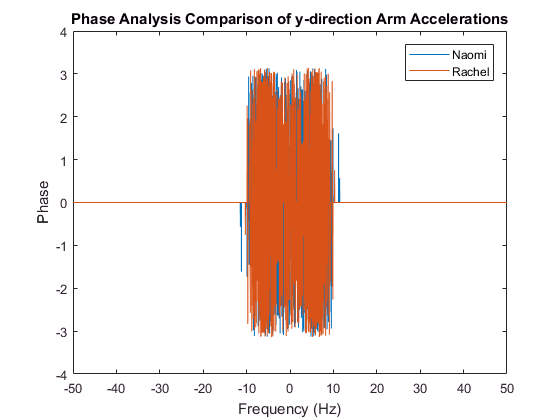

figure
plot(f_otf, phase_otf)
hold on
plot(f_otfr, phase_otfr)
hold off
legend('Naomi', 'Rachel')
title('Phase Analysis Comparison of y-direction Arm Accelerations')
xlabel('Frequency (Hz)')
ylabel('Phase')

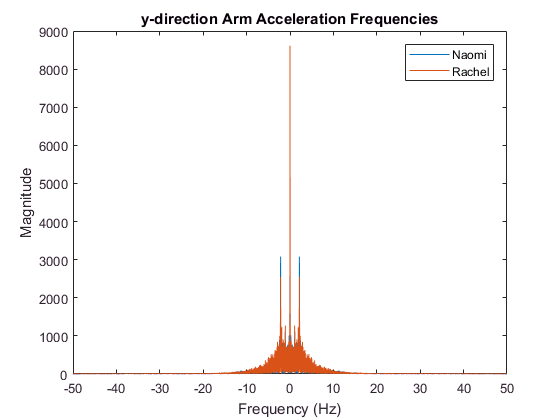

plot(f_otf, mag_otf)
hold on
plot(f_otfr, mag_otfr)
legend('Naomi', 'Rachel')
hold off
title('y-direction Arm Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

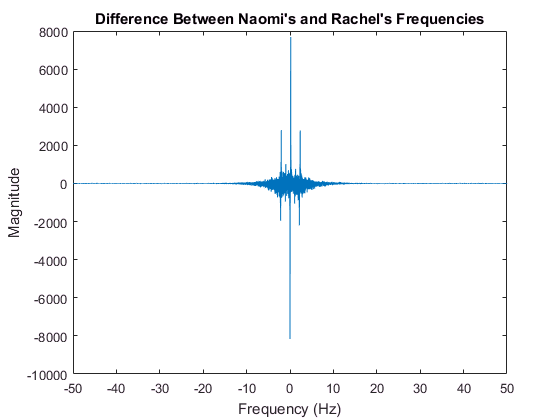

diff = mag_otf(1:length(mag_otfr)) - mag_otfr;
plot(f_otfr, diff)
title("Difference Between Naomi's and Rachel's Frequencies")
xlabel('Frequency (Hz)')
ylabel('Magnitude')

[f_otfn3, mag_otfn3, bpm_otfn3] = findbpm3D('onthefloornaomi.mat',Fs,1,length(onthefloornaomi))

f_otfn3 =   -49.9980  -49.9941  -49.9901  -49.9861  -49.9822  -49.9782  -49.9742  -49.9703  -49.9663  -49.9623  -49.9584  -49.9544  -49.9504  -49.9465  -49.9425  -49.9385  -49.9346  -49.9306  -49.9266  -49.9227  -49.9187  -49.9147  -49.9108  -49.9068  -49.9028  -49.8989  -49.8949  -49.8909  -49.8870  -49.8830  -49.8790  -49.8751  -49.8711  -49.8671  -49.8632  -49.8592  -49.8552  -49.8513  -49.8473  -49.8433  -49.8394  -49.8354  -49.8314  -49.8275  -49.8235  -49.8195  -49.8156  -49.8116  -49.8076  -49.8037


mag_otfn3 =     4.0738
    5.4426
    5.2310
    6.5608
    6.6219
    2.8441
    4.4310
    4.0305
    5.5361
    4.9521


bpm_otfn3 = 130.4089

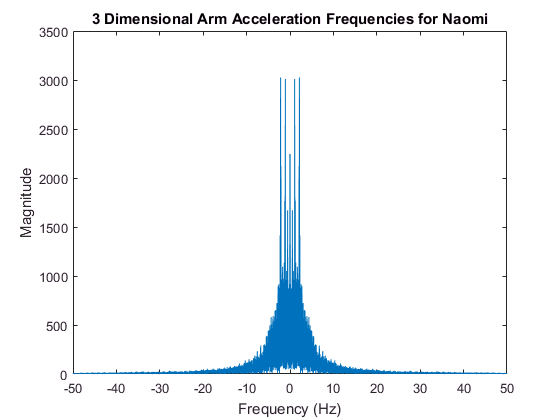

plot(f_otfn3,mag_otfn3)
title('3 Dimensional Arm Acceleration Frequencies for Naomi')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

[f_otfr3, mag_otfr3, bpm_otfr3] = findbpm3D('onthefloorrachel.mat',Fs,1,length(onthefloorrachel))

f_otfr3 =   -49.9980  -49.9940  -49.9901  -49.9861  -49.9821  -49.9781  -49.9741  -49.9702  -49.9662  -49.9622  -49.9582  -49.9542  -49.9503  -49.9463  -49.9423  -49.9383  -49.9343  -49.9304  -49.9264  -49.9224  -49.9184  -49.9144  -49.9105  -49.9065  -49.9025  -49.8985  -49.8945  -49.8906  -49.8866  -49.8826  -49.8786  -49.8746  -49.8707  -49.8667  -49.8627  -49.8587  -49.8547  -49.8508  -49.8468  -49.8428  -49.8388  -49.8349  -49.8309  -49.8269  -49.8229  -49.8189  -49.8150  -49.8110  -49.8070  -49.8030


mag_otfr3 =     4.1292
    9.9997
    9.5135
    5.4027
   10.2594
    9.4353
    3.4207
    4.0285
    3.8017
   12.2258


bpm_otfr3 = 63.9898

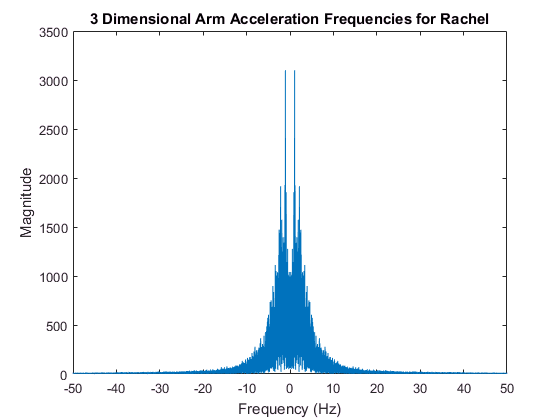

plot(f_otfr3,mag_otfr3)
title('3 Dimensional Arm Acceleration Frequencies for Rachel')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

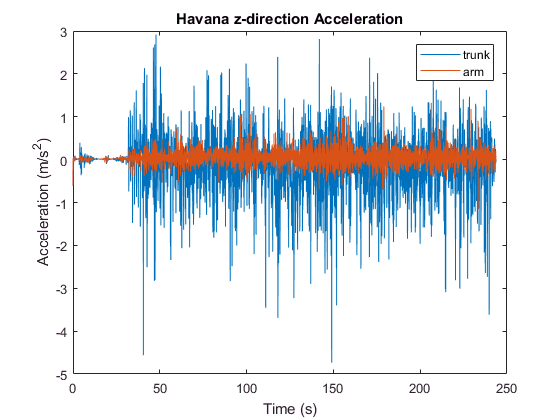

load havanaarm.mat
load havanatrunk.mat

N = length(havanaarm)-480;
t = linspace(0,N/Fs,N);
plot(t,havanaarm(481:end,7))
hold on
plot(t,havanatrunk(609:length(havanaarm)+(609-481),7))
hold off
legend('trunk','arm')
title('Havana z-direction Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

[f_h, mag_h, phase_, bpm_h] = findbpmphase('havanaarm.mat',Fs,'accel','y',481,length(havanaarm))

f_h =   -50.0000  -49.9959  -49.9918  -49.9877  -49.9836  -49.9795  -49.9754  -49.9713  -49.9672  -49.9631  -49.9590  -49.9549  -49.9508  -49.9466  -49.9425  -49.9384  -49.9343  -49.9302  -49.9261  -49.9220  -49.9179  -49.9138  -49.9097  -49.9056  -49.9015  -49.8974  -49.8933  -49.8892  -49.8851  -49.8810  -49.8769  -49.8728  -49.8687  -49.8646  -49.8605  -49.8564  -49.8523  -49.8481  -49.8440  -49.8399  -49.8358  -49.8317  -49.8276  -49.8235  -49.8194  -49.8153  -49.8112  -49.8071  -49.8030  -49.7989


mag_h =     3.0115
    2.4905
    9.4513
    8.9113
    7.5350
    5.0168
    3.5436
    1.7515
    4.5556
    6.5200


phase_ =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


bpm_h = 112.0414

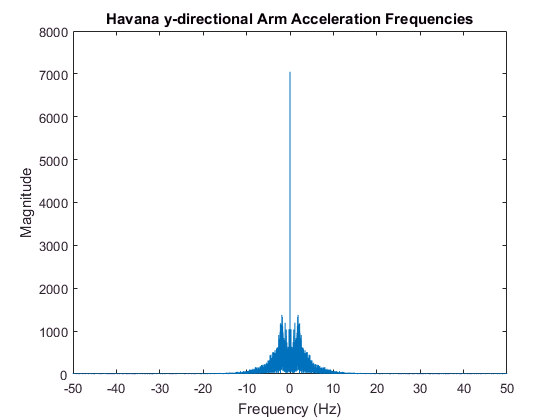

plot(f_h, mag_h)
title('Havana y-directional Arm Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

[f_ha, mag_ha, bpm_ha] = findbpm3D('havanaarm.mat',Fs,481, length(havanaarm))

f_ha =   -50.0000  -49.9959  -49.9918  -49.9877  -49.9836  -49.9795  -49.9754  -49.9713  -49.9672  -49.9631  -49.9590  -49.9549  -49.9508  -49.9466  -49.9425  -49.9384  -49.9343  -49.9302  -49.9261  -49.9220  -49.9179  -49.9138  -49.9097  -49.9056  -49.9015  -49.8974  -49.8933  -49.8892  -49.8851  -49.8810  -49.8769  -49.8728  -49.8687  -49.8646  -49.8605  -49.8564  -49.8523  -49.8481  -49.8440  -49.8399  -49.8358  -49.8317  -49.8276  -49.8235  -49.8194  -49.8153  -49.8112  -49.8071  -49.8030  -49.7989


mag_ha =     7.8195
   11.0104
   14.3301
   13.5201
   15.1275
    9.2316
    7.9695
   10.6276
    8.4034
   12.5342


bpm_ha = 26.3482

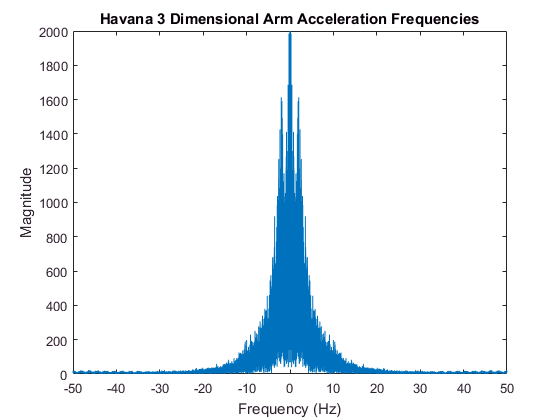

plot(f_ha,mag_ha)
title('Havana 3 Dimensional Arm Acceleration Frequencies')
ylim([0 2000])
xlabel('Frequency (Hz)')
ylabel('Magnitude')

[f_ht, mag_ht, phase_ht, bpm_ht] = findbpmphase('havanatrunk.mat',Fs,'accel','y',609,length(havanaarm)+(609-481))

f_ht =   -50.0000  -49.9959  -49.9918  -49.9877  -49.9836  -49.9795  -49.9754  -49.9713  -49.9672  -49.9631  -49.9590  -49.9549  -49.9508  -49.9466  -49.9425  -49.9384  -49.9343  -49.9302  -49.9261  -49.9220  -49.9179  -49.9138  -49.9097  -49.9056  -49.9015  -49.8974  -49.8933  -49.8892  -49.8851  -49.8810  -49.8769  -49.8728  -49.8687  -49.8646  -49.8605  -49.8564  -49.8523  -49.8481  -49.8440  -49.8399  -49.8358  -49.8317  -49.8276  -49.8235  -49.8194  -49.8153  -49.8112  -49.8071  -49.8030  -49.7989


mag_ht =     0.8632
    0.5609
    1.0946
    0.6943
    0.8461
    0.4685
    1.3213
    0.8550
    0.9857
    0.9677


phase_ht =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


bpm_ht = 104.6540

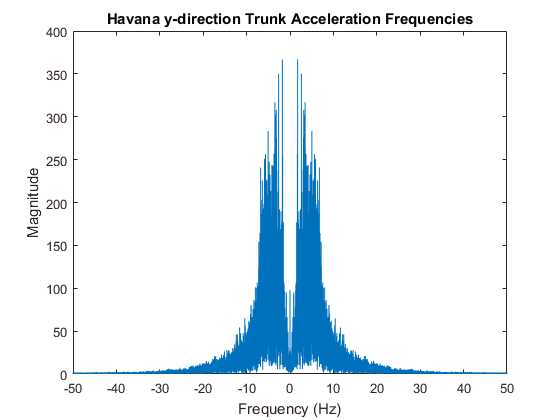

plot(f_ht,mag_ht)
title('Havana y-direction Trunk Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

function [f, mag, bpm] = findbpm3D(filename, Fs, start, final)
    file1 = cell2mat(struct2cell(load(filename)));
    file = file1(start:final,:);
    N = length(file(:,1));
    f = linspace(-Fs/2, Fs/2 - Fs/N,N) + Fs/(2*N)*mod(N,2);
    
    threeD = file(:,5)+file(:,6)+file(:,7);
    mag = fftshift(abs(fft(threeD)));
    
    positive = mag(f > 0.3);
    H = max(positive);
    bps = find(mag == H);
    bpm = abs(f(bps(1)))*60;
end

function [f, mag, phase, bpm] = findbpmphase(filename, Fs, sensor, direction, start, final)
    file1 = cell2mat(struct2cell(load(filename)));
    file = file1(start:final,:);
    N = length(file(:,1));
    t = linspace(0,N/Fs,N);
    f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);
    if strcmp(sensor,'accel')
        if strcmp(direction,'x')
            dir = 6;
        elseif strcmp(direction,'y')
            dir = 5;
        elseif strcmp(direction,'z')
            dir = 7;
        else
            dir = 5;
        end
    elseif strcmp(sensor,'gyro')
        if strcmp(direction,'x')
            dir = 3;
        elseif strcmp(direction,'y')
            dir = 2;
        elseif strcmp(direction,'z')
            dir = 4;
        else
            dir = 2;
        end
    end
    mag = fftshift(abs(fft(file(:,dir))));
    cp = fft(file(:,dir));
    lower_threshold = max(abs(fft(file(:,dir))))/100;
    upper_threshold = max(abs(fft(file(:,dir))))/50;
    clean_phase = abs(fft(file(:,dir)));
    lower_indeces = find(clean_phase < lower_threshold);
    upper_indeces = find(clean_phase > upper_threshold);
    cp(lower_indeces) = 0;
    cp(upper_indeces) = 0;
    phase = angle(fftshift(cp));
 
    positive = mag(f > 0.3);
    H = max(positive);
    bps = find(mag == H);
    bpm = abs(f(bps(1)))*60;
end